# Recognizing hand-written digits

## Loading the data

load digits.mat
A=azip;
D=dzip;
At=testzip;
Dt=dtest;
[m,n]=size(A);
k=10;

## Iterative k-means

P=iterative_k_means(A',k) ;
[P1,P2]=relaxed_k_means(A',k) ; 
P=P-ones(size(P));
P1=P1-ones(size(P1));
P2=P2-ones(size(P2));

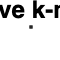

confusionchart(D,P,'Title','Iterative k-means','DiagonalColor',[0.8510 0.3255 0.0980] )

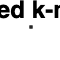

confusionchart(D,P1,'Title','Relaxed k-means','DiagonalColor',[0.8510 0.3255 0.0980] )

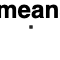

confusionchart(D,P2,'Title','Relaxed k-means using QR','DiagonalColor',[0.8510 0.3255 0.0980] )

We notice immediately that cluseter names have nothing to do with the digit they are 'predicting'. Let's change that!

## Correct confusion charts

Z=[2,7,4,6,8,1,3,9,5,0];
P_c=P;
for i=1:n
    for j=1:10
        if P_c(i)==j-1
            P(i)=Z(j);
            break
        end
    end
end

Z1=[0,7,9,6,4,1,3,2,8,0];
P1_c=P1;

for i=1:n
    for j=1:k
        if P1_c(i)==j-1
            P1(i)=Z1(j);
            break
        end
    end
end

Z2=[7,0,4,2,8,6,5,3,9,1];
P2_c=P2;

for i=1:n
    for j=1:k
        if P2_c(i)==j-1
            P2(i)=Z2(j);
            break
        end
    end
end

Now we can truly use the confusion matrix and calculate the prediction error on the traing set, whis is of course not a good meassure of the true prediction error.

confusionchart(D,P,'Title','Iterative k-means')

confusionchart(D,P1,'Title','Relaxed k-means')

confusionchart(D,P2,'Title','Relaxed k-means using QR')

C=confusionmat(D,P);
C1=confusionmat(D,P1);
C2=confusionmat(D,P2);


sum(diag(C))/sum(C,"all")

ans = 0.6883

sum(diag(C1))/sum(C1,"all")

ans = 0.7469

sum(diag(C2))/sum(C2,"all")

ans = 0.5923

## Predictions

In order to make predictions we need the centroids.

M=zeros(256,10);
M1=zeros(256,10);
M2=zeros(256,10);


for i=0:9
    M(:,i+1)=mean(A(:,P==i),2); 
end

M1=zeros(m,k);
for i=0:9
    M1(:,i+1)=mean(A(:,P1==i),2); 
end

M2=zeros(m,k);
for i=0:9
    M2(:,i+1)=mean(A(:,P2==i),2); 
end

Time to make the predictions and confusion matrix as well as the prediction error.

s=size(Dt);
nt=size(At,2);
pM=zeros(s);
pM1=zeros(s);
pM2=zeros(s);


for i = 1:nt
    min=norm(At(:,i)-M(:,1));
    num=0;
    for j=2:10
        if min>=norm(At(:,i)-M(:,j))
            min=norm(At(:,i)-M(:,j));
            num=j-1;
        end
    end

    pM(i)=num;

end

for i = 1:nt
    min=norm(At(:,i)-M1(:,1));
    num=0;
    for j=2:10
        if min>=norm(At(:,i)-M1(:,j))
            min=norm(At(:,i)-M1(:,j));
            num=j-1;
        end
    end

    pM1(i)=num;

end

for i = 1:nt
    min=norm(At(:,i)-M2(:,1));
    num=0;
    for j=2:10
        if min>=norm(At(:,i)-M2(:,j))
            min=norm(At(:,i)-M2(:,j));
            num=j-1;
        end
    end

    pM2(i)=num;

end

## Test error estimate

confusionchart(Dt,pM,'Title','Iterative k-means')

confusionchart(Dt,pM1,'Title','Relaxed k-means')

confusionchart(Dt,pM2,'Title','Relaxed k-means using QR')

pC=confusionmat(Dt,pM);
pC1=confusionmat(Dt,pM1);
pC2=confusionmat(Dt,pM2);

sum(diag(pC))/sum(pC,"all")

ans = 0.6522

sum(diag(pC1))/sum(pC1,"all")

ans = 0.6986

sum(diag(pC2))/sum(pC2,"all")

ans = 0.6069

$70 \%$ accuracy.

# Classifying digits using spectral clustering with Gaussian kernels

#### 
$$\sigma=50$$


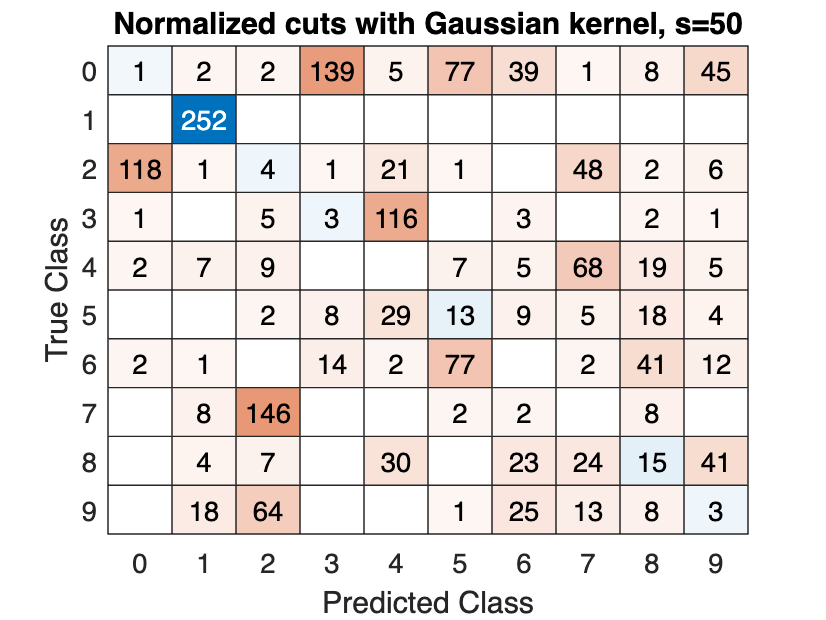

W=gaussian_kernel(A',50); % A' for variables in rows
P=normalized_cuts(W,10);
P=P-ones(size(P));
confusionchart(D,P,'Title','Normalized cuts with Gaussian kernel, s=50');

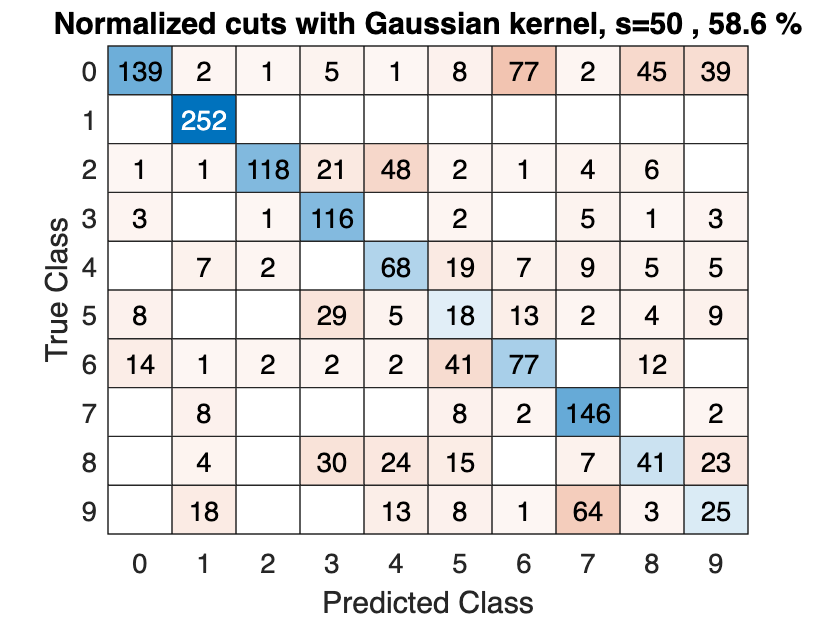

P_new=P;
X=[2,1,7,0,3,6,9,4,5,8];
for i=1:n
    for j=1:k
        if P_new(i)==j-1
            P(i)=X(j);
            break
        end
    end
end
confusionchart(D,P,'Title','Normalized cuts with Gaussian kernel, s=50 , 58.6 %')

c=confusionmat(D,P);
sum(diag(c))/sum(c,'all')

ans = 0.5858

#### 
$$\sigma=45$$


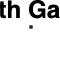

W=gaussian_kernel(A',45); % A' for variables in rows
P=normalized_cuts(W,10);
P=P-ones(size(P));
confusionchart(D,P,'Title','Normalized cuts with Gaussian kernel, s=45')

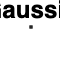

P_new=P;
X=[8,0,7,6,3,2,9,4,5,1];
for i=1:n
    for j=1:k
        if P_new(i)==j-1
            P(i)=X(j);
            break
        end
    end
end
confusionchart(D,P,'Title','Normalized cuts with Gaussian kernel, s=45 , 53,5%')

c=confusionmat(D,P);
sum(diag(c))/sum(c,'all')

ans = 0.5354

#### 
$$\sigma=55$$


W=gaussian_kernel(A',55); % A' for variables in rows
P=normalized_cuts(W,10);
P=P-ones(size(P));
confusionchart(D,P,'Title','Normalized cuts with Gaussian kernel, s=55')

P_new=P;
X=[9,1,7,0,3,2,6,4,5,8];
for i=1:n
    for j=1:k
        if P_new(i)==j-1
            P(i)=X(j);
            break
        end
    end
end
confusionchart(D,P,'Title','Normalized cuts with Gaussian kernel, s=55 , 55.5%');

c=confusionmat(D,P);
sum(diag(c))/sum(c,'all')

ans = 0.5548

## Prediction using $\sigma=50$

W=gaussian_kernel(A',50); % A' for variables in rows
P=normalized_cuts(W,10);
P=P-ones(size(P));
P_new=P;
X=[2,1,7,0,3,6,9,4,5,8];
for i=1:n
    for j=1:k
        if P_new(i)==j-1
            P(i)=X(j);
            break
        end
    end
end

for i=0:9
    M(:,i+1)=mean(A(:,P==i),2); 
end

s=size(Dt);
nt=size(At,2);
pM=zeros(s);
pM1=zeros(s);
pM2=zeros(s);


for i = 1:nt
    min=norm(At(:,i)-M(:,1));
    num=0;
    for j=2:10
        if min>=norm(At(:,i)-M(:,j))
            min=norm(At(:,i)-M(:,j));
            num=j-1;
        end
    end

    pM(i)=num;

end

confusionchart(Dt,pM,'Title','Normalized cuts with Gaussian kernel, s=55 , 56.5%')

pC=confusionmat(Dt,pM);
sum(diag(pC))/sum(pC,"all")

ans = 0.5650

## Conslusion

Without exhaustive search for a good $\sigma$ parameter we managed to achive ~$60$% acuuracy, which proves how powerfull spectral clustering is since it would most likely not be used in this scenario. It is impressive how it does not preform (significantly) worse than previous methods.